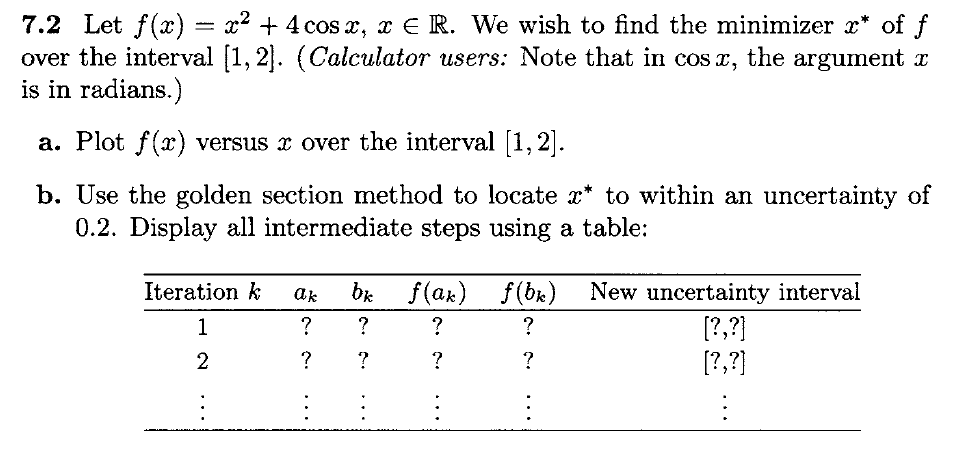

a)

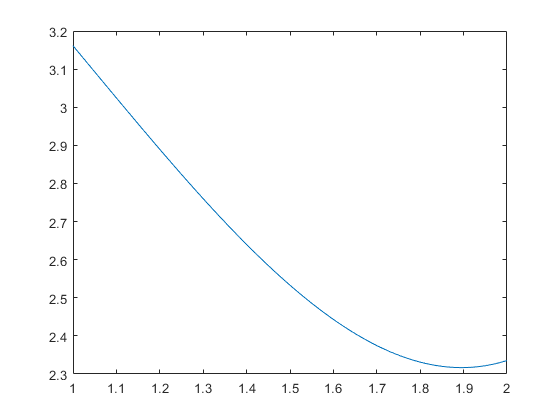

x = 1:.01:2;
f_x = x.^2+4*cos(x);
plot(x,f_x)

b) 

p = (3-sqrt(5))/2

p = 0.3820

% (1-p)^N <= 0.2/2-1

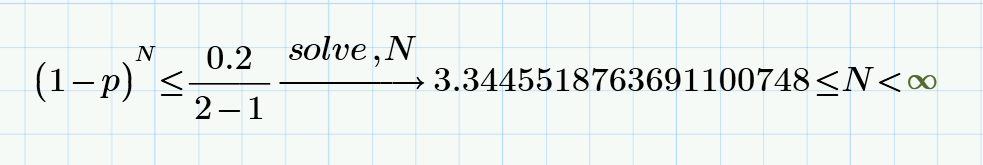

So we need more than 3.34 steps, eg 4 steps

clear
clc
p = (3-sqrt(5))/2;
% (1-p)^N <= 0.2/2-1
a0 = 1;
b0 = 2;

a_k = a0;
b_k = b0;
a_k_old = a_k;
b_k_old = b_k;
firstrun = 1;
for k=1:4
    if(firstrun == 1)
        a_k = a_k_old+p*(b_k_old-a_k_old);
        b_k = a_k_old+(1-p)*(b_k_old-a_k_old);
        f_x_ak = a_k.^2+4*cos(a_k);
        f_x_bk = b_k.^2+4*cos(b_k);
    else
        if(f_x_ak > f_x_bk)
        a_k_new = b_k;
        b_k_new = a_k_old+(1-p)*(b_k_old-a_k_old);
        else
        b_k_new = a_k;
        a_k_new = a_k_old+p*(b_k_old-a_k_old);
        end
        f_x_ak = a_k_new.^2+4*cos(a_k_new);
        f_x_bk = b_k_new.^2+4*cos(b_k_new);
        a_k = a_k_new;
        b_k = b_k_new;
    end
    if(f_x_ak > f_x_bk)
        interval = [a_k b_k_old];
        a_k_old = a_k;
    else
        interval = [a_k_old b_k];
        b_k_old = b_k;
    end
    firstrun = 0;
    iter(k,:) = [k a_k b_k f_x_ak f_x_bk interval]
end

iter =     1.0000    1.3820    1.6180    2.6607    2.4292    1.3820    2.0000


iter =     1.0000    1.3820    1.6180    2.6607    2.4292    1.3820    2.0000
    2.0000    1.6180    1.7639    2.4292    2.3437    1.6180    2.0000


iter =     1.0000    1.3820    1.6180    2.6607    2.4292    1.3820    2.0000
    2.0000    1.6180    1.7639    2.4292    2.3437    1.6180    2.0000
    3.0000    1.7639    1.8541    2.3437    2.3196    1.7639    2.0000


iter =     1.0000    1.3820    1.6180    2.6607    2.4292    1.3820    2.0000
    2.0000    1.6180    1.7639    2.4292    2.3437    1.6180    2.0000
    3.0000    1.7639    1.8541    2.3437    2.3196    1.7639    2.0000
    4.0000    1.8541    1.9098    2.3196    2.3171    1.8541    2.0000


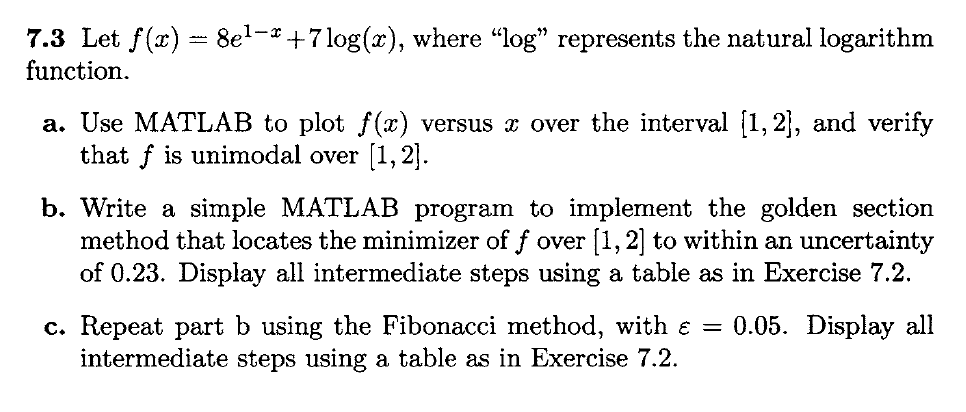

a)

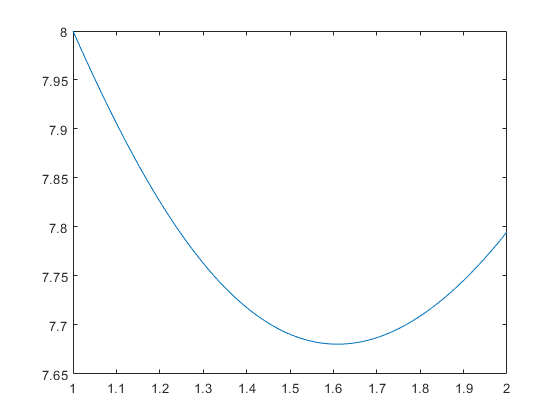

clear, clc;
x = 1:.01:2;
f_x = 8*exp(1-x)+7*log(x);
plot(x,f_x)

b)

clear
clc
p = (3-sqrt(5))/2;
% (1-p)^N <= 0.2/2-1
a0 = 1;
b0 = 2;

a_k = a0;
b_k = b0;
a_k_old = a_k;
b_k_old = b_k;
firstrun = 1;
for k=1:4
    if(firstrun == 1)
        a_k = a_k_old+p*(b_k_old-a_k_old);
        b_k = a_k_old+(1-p)*(b_k_old-a_k_old);
        f_x_ak = 8*exp(1-a_k)+7*log(a_k);
        f_x_bk = 8*exp(1-b_k)+7*log(b_k);
    else
        if(f_x_ak > f_x_bk)
        a_k_new = b_k;
        b_k_new = a_k_old+(1-p)*(b_k_old-a_k_old);
        else
        b_k_new = a_k;
        a_k_new = a_k_old+p*(b_k_old-a_k_old);
        end
        f_x_ak = 8*exp(1-a_k_new)+7*log(a_k_new);
        f_x_bk = 8*exp(1-b_k_new)+7*log(b_k_new);
        a_k = a_k_new;
        b_k = b_k_new;
    end
    if(f_x_ak > f_x_bk)
        interval = [a_k b_k_old];
        a_k_old = a_k;
    else
        interval = [a_k_old b_k];
        b_k_old = b_k;
    end
    firstrun = 0;
    iter(k,:) = [k a_k b_k f_x_ak f_x_bk interval]
end

iter =     1.0000    1.3820    1.6180    7.7247    7.6805    1.3820    2.0000


iter =     1.0000    1.3820    1.6180    7.7247    7.6805    1.3820    2.0000
    2.0000    1.6180    1.7639    7.6805    7.6995    1.3820    1.7639


iter =     1.0000    1.3820    1.6180    7.7247    7.6805    1.3820    2.0000
    2.0000    1.6180    1.7639    7.6805    7.6995    1.3820    1.7639
    3.0000    1.5279    1.6180    7.6860    7.6805    1.5279    1.7639


iter =     1.0000    1.3820    1.6180    7.7247    7.6805    1.3820    2.0000
    2.0000    1.6180    1.7639    7.6805    7.6995    1.3820    1.7639
    3.0000    1.5279    1.6180    7.6860    7.6805    1.5279    1.7639
    4.0000    1.6180    1.6738    7.6805    7.6838    1.5279    1.6738


c) Fibonacci method

clear,clc
f = @myF;

left = 1;
right = 2;
uncert = 0.23;
epsilon = 0.05;

F(1)=1;
F(2)=1;

N = 0;

while F(N+2) < (1+2*epsilon)*(right-left)/uncert
    F(N+3) = F(N+2)+F(N+1);
    N=N+1;
end
N % We need 3 iterations to complete

N = 3


lower = 'a';
a = left+(F(N+1)/F(N+2))*(right-left);
f_a = f(a);

for i=1:N
    if i ~= N
        rho = 1-F(N+2-i)/F(N+3-i) % pk = 1-(FN-k+1/Fn-k+2)
    else
        rho = 0.5-epsilon  % 1/2 - epsilon
    end
    
    if lower == 'a'
        b=a;
        f_b=f_a;
        a=left+rho*(right-left); % a1 = a0+p1(b0-a0) % a2 = a0+p2(b1-a0) etc.
        f_a=f(a);
    else
        a=b;
        f_a=f_b;
        b=left+(1-rho)*(right-left); % b1 = a0+(1-p1)(b0-a0) & b2 = a1 etc.
        f_b=f(b);
    end
    
    if f_a<f_b
        right=b;
        lower='a';
    else
        left=a;
        lower='b';
    end
    New_Interval = [left,right]
    
    Fibon(i,:) = [i rho a b f_a f_a New_Interval]
end

rho = 0.4000

New_Interval =     1.4000    2.0000


Fibon =     1.0000    0.4000    1.4000    1.6000    7.7179    7.7179    1.4000    2.0000


rho = 0.3333

New_Interval =     1.4000    1.8000


Fibon =     1.0000    0.4000    1.4000    1.6000    7.7179    7.7179    1.4000    2.0000
    2.0000    0.3333    1.6000    1.8000    7.6805    7.6805    1.4000    1.8000


rho = 0.4500

New_Interval =     1.5800    1.8000


Fibon =     1.0000    0.4000    1.4000    1.6000    7.7179    7.7179    1.4000    2.0000
    2.0000    0.3333    1.6000    1.8000    7.6805    7.6805    1.4000    1.8000
    3.0000    0.4500    1.5800    1.6000    7.6812    7.6812    1.5800    1.8000


7.10) Secant

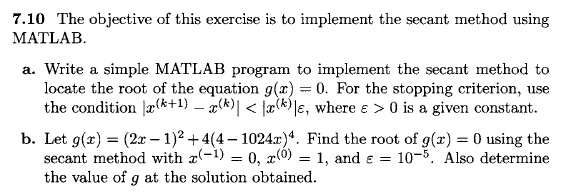

clear, clc
syms x
g = @(x)(2*x - 1)^2 + 4*(4 - 1024*x)^4;

uncert = 10^(-5);
xcurr = 0;
xnew = 1;

g_curr=feval(g,xcurr);
while abs(xnew-xcurr)>xcurr*uncert % define how many digits should they be differ
xold=xcurr;
xcurr=xnew;
g_old=g_curr;
g_curr=feval(g,xcurr);
xnew=(g_curr*xold-g_old*xcurr)/(g_curr-g_old);
end %while
%print out solution and value of g(x)
x=xnew

x = 0.0039

g_curr

g_curr = 0.9846



%%secant(g, 0, 1, 0.00001)

final_point = 0.0039

value = 0.9846

function y = myF(x)
    y = 8*exp(1-x)+7*log(x);
end
